% Define AUV dimensions
L = 2.5;    % Hull length in meters
D = 0.35;   % Hull diameter in meters
tmax = 0.1*D; % maximum thickness of the fin as a percentage of the diameter
trapezoid_factor = 0.5;

% Determine the appropriate fin  type based on AUV dimensions
if L/D >= 10
    disp ('control_surface_type = hydrofoil');
else
   disp ('control_surface_type = fin');
end

control_surface_type = fin



%CG distance
CG=0.45 * (L + 2.2)/2;
% Define parameters for optimization
syms x    % Symbolic variable for fin  position
f(x) = -x^2*(L-x);    % Objective function for optimization (negative of pitch moment)
x0 = L/2;    % Initial guess for fin  position
x1=L/2+CG;   %Increase in span
lb = 0;    % Lower bound for fin  position
ub = L;    % Upper bound for fin  position


% Determine the appropriate fin  area and span based on fin  type and desired maneuverability
control_surface_type = "fin";   % Type of fin  (options are "hydrofoil" and "fin")
span = input("Enter the span of the fin  in meters: "); % Span of the fin  in meters

% Perform optimization
if span <=1
    x_opt = fmincon(@(x) double(subs(f,x)),x0,[],[],[],[],lb,ub);
elseif span>1
    x_opt = fmincon(@(x) double(subs(f,x)),x1,[],[],[],[],lb,ub);
    new_span=input("Enter new span value for fin in meters:");
    x_opt= x_opt + 0.2*new_span;
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Calculate taper ratio based on desired span and chord lengths
sweep_angle = atan(L/span); % sweep angle of the fin in radians
root_chord = (2/(1+trapezoid_factor))*span/tan(sweep_angle); % root chord length
tip_chord = trapezoid_factor*root_chord; % tip chord length
taper_ratio = tip_chord/root_chord; % taper ratio
MAC = (2/3)*root_chord*((1+taper_ratio+taper_ratio^2)/(1+taper_ratio)); % mean aerodynamic chord
S = span*MAC; % planform area
b = span/2; % half-span
thickness = tmax*D; % thickness of the fin
I = (1/12)*thickness*(root_chord^3+tip_chord^3+root_chord^2*tip_chord+root_chord*tip_chord^2); % moment of inertia about the root chord

if span<=1
% Calculate fin area based on taper ratio and chord lengths
area = (2/3)*root_chord*(1+taper_ratio+sqrt(1+taper_ratio^2))*span;
else 

% Calculate fin area based on taper ratio and chord lengths
area = (2/3)*root_chord*(1+taper_ratio+sqrt(1+taper_ratio^2))*new_span;
end

if area > 10
    control_surface_type = "hydrofoil"; % switch to hydrofoil
    disp("The calculated area exceeds 10 square meters. Please perform appropriate calculations for a hydrofoil fin .")
else
    recommended_airfoil = ""; % declare recommended airfoil variable
    if area > 3
        maneuverability = "low";    % fin  area in square meter
        recommended_airfoil = "flat plate or Clark Y foil";
    elseif (1 < area) && (area < 3)
        maneuverability = "medium";    % fin  area in square meters
        recommended_airfoil = "NACA 6-digit foil";
    elseif  area < 1
        maneuverability = "high";   % fin  area in square meters
        recommended_airfoil = "NACA 4-series foil";
    else 
        maneuverability = "cannot be determined";
    end
end

disp("The recommended airfoil for the selected fin  is: " + recommended_airfoil)

The recommended airfoil for the selected fin  is: NACA 4-series foil



    
    switch control_surface_type
        case "fin"
            disp("The fin  area is " + area + " square meters, and the maneuverability level is " + maneuverability + ".")
        case "hydrofoil"
            error('Invalid fin  type. Options are "hydrofoil" and "fin".')
    end

The fin  area is 0.031955 square meters, and the maneuverability level is high.


% Calculate position of the fin  along the hull
position = 0.3*L;   % Position of the fin  along the hull in meters

% Define the z-coordinates of the fin
Z_root = 0.2 * D; % Distance from bottom of the hull to root of fin
Z_tip = 0.5 * D; % Distance from bottom of the hull to tip of fin

% Calculate the chord of the fin using the trapezoidal formula
chord = 2 * area / (span * (1 + taper_ratio));

% Calculate the y-coordinates of the fin using the trapezoidal formula
y_tip = span / 2;
y_root = -span / 2;

% Display results
disp(['fin  type: ', control_surface_type])

    "fin  type: "    "fin"



disp(['fin  area: ', num2str(area), ' m^2'])

fin  area: 0.031955 m^2


disp(['fin  span: ', num2str(span), ' m'])

fin  span: 0.325 m


disp(['fin  chord: ', num2str(chord), ' m'])

fin  chord: 0.1311 m


disp(['fin  taper ratio: ', num2str(taper_ratio)])

fin  taper ratio: 0.5


disp(['Optimal fin  position: ', num2str(x_opt), ' m'])

Optimal fin  position: 1.6667 m


disp(['Position of fin  along hull: ', num2str(position), ' m'])

Position of fin  along hull: 0.75 m


disp(['Distance from bottom of the hull to root of fin:', num2str(Z_root),'m'])

Distance from bottom of the hull to root of fin:0.07m


disp(['Distance from bottom of the hull to tip of fin:', num2str(Z_tip),'m'])

Distance from bottom of the hull to tip of fin:0.175m


disp(['Centre of Gravity:', num2str(CG),'m'])

Centre of Gravity:1.0575m


disp(['Root Chord = ',num2str(root_chord),' m']);

Root Chord = 0.056333 m


disp(['Tip Chord = ',num2str(tip_chord),' m']);

Tip Chord = 0.028167 m


disp(['Taper Ratio = ',num2str(taper_ratio)]);

Taper Ratio = 0.5


disp(['thickness = ',num2str(thickness)]);

thickness = 0.01225


disp(['MAC = ',num2str(MAC)]);

MAC = 0.043815


disp(['MoI = ',num2str(I)]);

MoI = 3.4218e-07


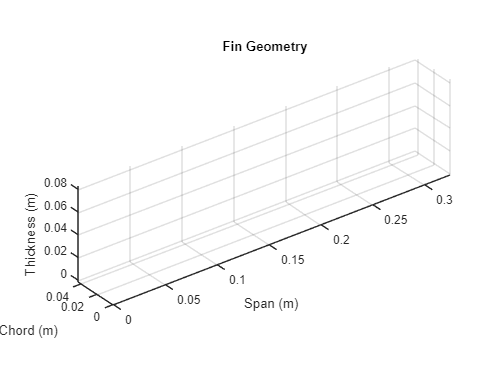


% Define airfoil coordinates
x_airfoil = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0, 0.9, 0.8, 0.7, 0.6, 0.5, 0.4, 0.3, 0.2, 0.15];
y_airfoil = [0.0, 0.0, 0.01, 0.02, 0.05, 0.09, 0.15, 0.22, 0.3, 0.39, 0.5, 0.61, 0.7, 0.78, 0.85, 0.91, 0.95, 0.98, 1.0, 1.0];

% Calculate taper ratio and average chord length
taper_ratio = tip_chord/root_chord;
avg_chord = 2/3*root_chord*(1 + taper_ratio + taper_ratio^2)/(1 + taper_ratio);

% Define the wing geometry as a 3D surface using airfoil data
[x, y] = meshgrid(linspace(0,span,50), linspace(0,avg_chord,20));
z = y_airfoil' .* (tip_chord - (tip_chord - root_chord)/span.*x) + ...
    (avg_chord-y_airfoil') .* (tip_chord-root_chord)/span.*x;

% Plot the wing geometry
figure;
surf(x, y, z);
axis equal;
xlabel('Span (m)');
ylabel('Chord (m)');
zlabel('Thickness (m)');
title('Fin Geometry');

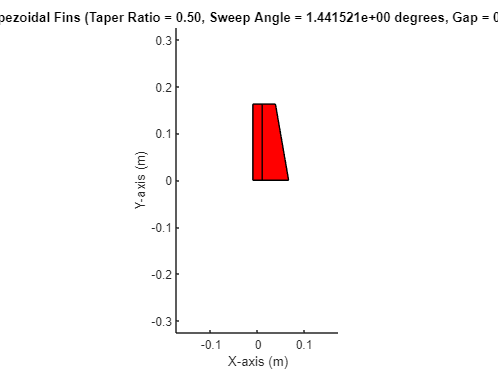




% Calculate position of fins
fin_pos = (D/2)*cosd(sweep_angle/2);
gap_size = 0.02; % size of gap between fins

% Define fin coordinates
x1 = [0, root_chord, tip_chord, 0]-gap_size/2; % X-coordinates of vertices for first fin
x2 = [0, root_chord, tip_chord, 0]+gap_size/2; % X-coordinates of vertices for second fin
y = [0, 0, span, span]; % Y-coordinates of vertices

% Plot fins with gap
figure;
patch(x1, y, 'r');
hold on;

patch(x2, y, 'r');

axis equal;
xlim([-span/2-gap_size/2, span/2+gap_size/2]);
ylim([-span, span]);
xlabel('X-axis (m)');
ylabel('Y-axis (m)');
title(sprintf('Trapezoidal Fins (Taper Ratio = %.2f, Sweep Angle = %d degrees, Gap = %.2f m)', taper_ratio, sweep_angle, gap_size));